clf;
homedir='/Users/editabulovaite/Documents/PhD_Year3/Data';

dirNameForFileName=strrep(homedir,'/','-slash-'); %if the dirName is in fact a path containing several directories, we substitute any / to the string -slash- as / is not a valid file name character
dirNameForFileName=strrep(dirNameForFileName,'\','-slash-');

delimiter='\t';

data=dir('coloc_subtype_remaining_matrix_for_heatmap_noType2.csv');
data = readtable(data.name);


heatmapmatrix = data(1:109,2:31);
heatmapmatrix = table2array(heatmapmatrix);

regionnames = data(1:109,1);
regionnames = table2array(regionnames);
regionnames=categorical(regionnames);


heatmapmatrix(isnan(heatmapmatrix)) = 0;
c=[0.8 0.8 0.8;1 1 1;0.94 0.64 0.54;0.92 0.45 0.33;0.83 0.26 0.2;0.66 0.15 0.13]

c =     0.8000    0.8000    0.8000
    1.0000    1.0000    1.0000
    0.9400    0.6400    0.5400
    0.9200    0.4500    0.3300
    0.8300    0.2600    0.2000
    0.6600    0.1500    0.1300



h=heatmap(heatmapmatrix,"GridVisible","off",'ColorScaling',"scaledrows")

h =   HeatmapChart with properties:

        XData: {30×1 cell}
        YData: {109×1 cell}
    ColorData: [109×30 double]

  Show all properties


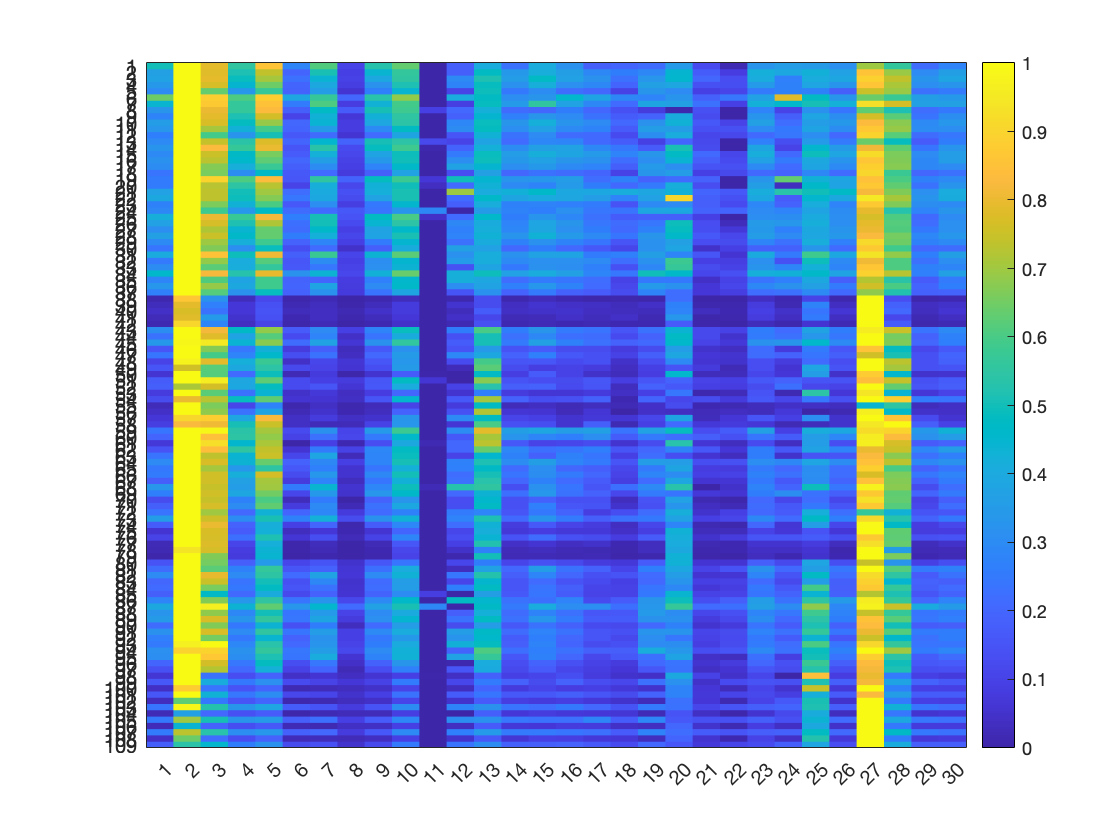

h =   HeatmapChart with properties:

        XData: {30×1 cell}
        YData: {109×1 cell}
    ColorData: [109×30 double]

  Show all properties


h.Colormap = parula